# HW5: Pearson correlation

Exercise:

Let's examine the relationship between the two measured variables, wing length and tail length, in cm

% Create a table containing the data
wing_length = [10.4, 10.8, 11.1, 10.2, 10.3, 10.2, 10.7, 10.5, 10.8, 11.2, 10.6, 11.4];
tail_length = [7.4, 7.6, 7.9, 7.2, 7.4, 7.1, 7.4, 7.2, 7.8, 7.7, 7.8, 8.3];
data = table(wing_length', tail_length', 'VariableNames', {'wing length', 'tail length'});
n = 12

n = 12

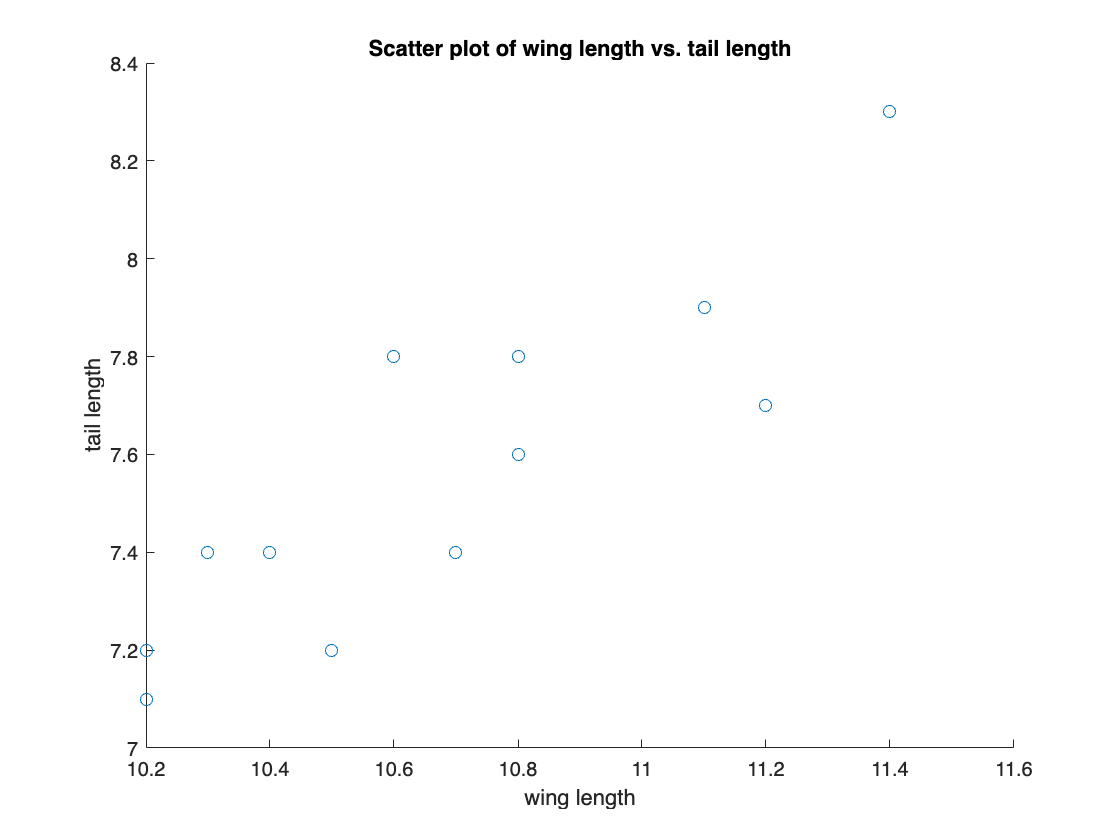


% Create a scatter plot of x vs. y
scatter(wing_length, tail_length);
xlabel('wing length');
ylabel('tail length');
title('Scatter plot of wing length vs. tail length');

% Calculate the pearson correlation manually

% Calculate the mean of x and y
mean_wing = mean(wing_length);
mean_tail = mean(tail_length);

% Calculate the Pearson correlation coefficient manually
numerator = sum((wing_length - mean_wing) .* (tail_length - mean_tail));
denominator_wing = sqrt(sum((wing_length - mean_wing).^2));
denominator_tail = sqrt(sum((tail_length - mean_tail).^2));
correlation_coefficient = numerator / (denominator_wing * denominator_tail);

% Display the result
fprintf('Pearson Correlation Coefficient (r): %.4f\n', correlation_coefficient);

Pearson Correlation Coefficient (r): 0.8704


% Calculate the pearson correlation using the function, corrcoef
correlation_matrix = corrcoef(wing_length, tail_length);
correlation_coefficient = correlation_matrix(1, 2);

% Display the result
fprintf('Pearson Correlation Coefficient (r): %.4f\n', correlation_coefficient);

Pearson Correlation Coefficient (r): 0.8704


% Calculate the standard error
error = sqrt((1 - correlation_coefficient)./(n - 2))

error = 0.1139


% Calculate confidence intervals

    % Take Fisher's z-transformation of r
    z = 0.5 .* log((1+correlation_coefficient)./(1-correlation_coefficient))

z = 1.3345


    % Compute its standard deviation
    s_z = sqrt(1 ./ n - 3)

s_z = 0.0000 + 1.7078i


    % Compute confidence intervals in this z-space
    % idk how to use norminv or the z calculator ... confused